s = tf("s");
G_original = 10 / ( (s+1)*(s+5) )


G_original =
 
       10
  -------------
  s^2 + 6 s + 5
 
Continuous-time transfer function.
Model Properties


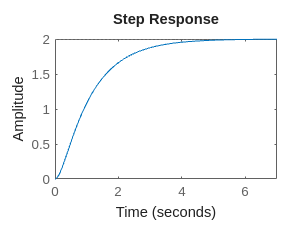


step(G_original,7); 


% Como a resposta em malha aberta tem formato de um "S" na origem, usa o
% primeiro método

%L, T e K são extraidos pela análise do gráfico do exercicio
L = 0.106;
T = 1.62 - 0.106;
K = 2;

G_estimada = (K * exp(-L * s)) / (T*s + 1)


G_estimada =
 
                       2
  exp(-0.106*s) * -----------
                  1.514 s + 1
 
Continuous-time transfer function.
Model Properties



% como é PID 
% Kp = 1.2 * (T/L); Ti = 2 * L; Td = 0.5 * L 
Kp = 1.2 * (T/L);
Ti = 2 * L;
Td = 0.5 * L ;
fprintf("Kp: %.3f\nTi: %.3f\nTd: %.3f", Kp, Ti, Td)

Kp: 17.140
Ti: 0.212
Td: 0.053


% como C(s) = Kp*(1+(1/(Ti*s))+Td*s)
C = Kp*(1+(1/(Ti*s))+Td*s)


C =
 
  0.1926 s^2 + 3.634 s + 17.14
  ----------------------------
            0.212 s
 
Continuous-time transfer function.
Model Properties


a = 0.1926/0.212;
b = 3.634/0.212;
c = 17.14/0.212;
fprintf("C(s) = (%.3f*s^2 + %.3f*s + %.3f)/s", a, b, c)

C(s) = (0.908*s^2 + 17.142*s + 80.849)/s


G_mf_c = feedback (C * G_original, 1)


G_mf_c =
 
       1.926 s^2 + 36.34 s + 171.4
  --------------------------------------
  0.212 s^3 + 3.198 s^2 + 37.4 s + 171.4
 
Continuous-time transfer function.
Model Properties


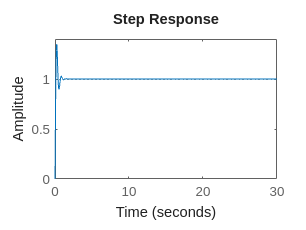

step(G_mf_c,30);


% Analisando o gráfico acima foi observado um Mp de (1.347 - 1)*100
Mp = 1.347 - 1;
fprintf("Mp: %.3f %%", Mp*100)

Mp: 34.700 %

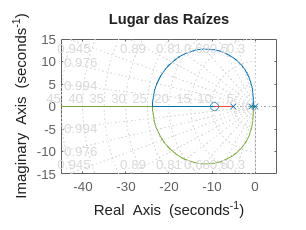


% Lugar das raízes
figure;
rlocus(C * G_original);
title('Lugar das Raízes');
grid on;


% Para que o sobressinal seja de aproximadamente 25%
% é preciso achar outro Td
Td = 0.0747 % --> Não sei achar o novo Td

Td = 0.0747


C = Kp*(1+(1/(Ti*s))+Td*s)


C =
 
  0.2714 s^2 + 3.634 s + 17.14
  ----------------------------
            0.212 s
 
Continuous-time transfer function.
Model Properties


a = 0.2714/0.212;
b = 3.634/0.212;
c = 17.14/0.212;
fprintf("C(s) = (%.3f*s^2 + %.3f*s + %.3f)/s", a, b, c)

C(s) = (1.280*s^2 + 17.142*s + 80.849)/s


G_mf_c = feedback (C * G_original, 1)


G_mf_c =
 
       2.714 s^2 + 36.34 s + 171.4
  --------------------------------------
  0.212 s^3 + 3.986 s^2 + 37.4 s + 171.4
 
Continuous-time transfer function.
Model Properties


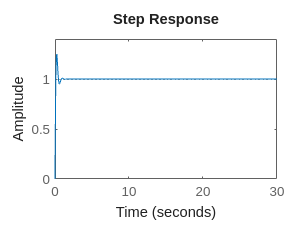

step(G_mf_c,30);


Mp = 1.2502 - 1;
fprintf("Mp: %.3f %%", Mp*100)

Mp: 25.020 %